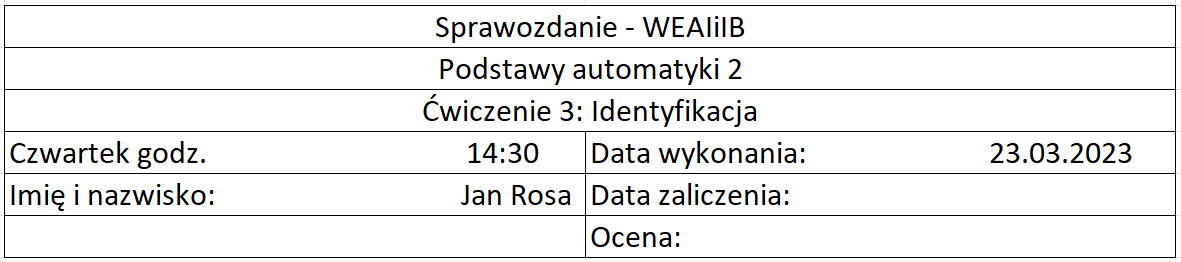

## Cel ćwiczenia 

Celem ćwiczenia jest zapoznanie się z przykładami identyfikacji parametrów modelu zastępczego rzeczywistego obiektu regulacji. Obiekt rzeczywisty jest doświadczalnym obiektem cieplnym (system dynamiczny nieskończenie wymiarowy)

Przebiegi czasowe sygnałów z czujników po wstępnym skalowaniu:

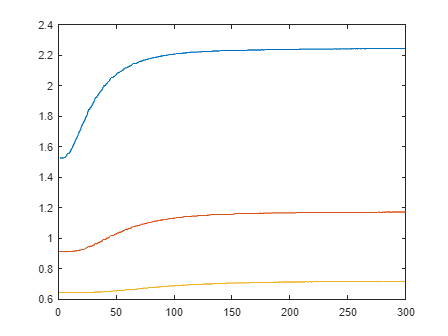

load pomiary_3out.mat
plot(pomiary_3out)

### Aproksymacja Kupfmullera obiektem 1rz z opóźnieniem

y1=pomiary_3out(:,1) - pomiary_3out(1,1);
y2=pomiary_3out(:,2) - pomiary_3out(1,2);
y3=pomiary_3out(:,3) - pomiary_3out(1,3);
t = 1:300;

Parametry obiektów

k1=(y1(300,1)-y1(1,1))/1.0; T1 = 30; theta1 = 7;
k2=(y2(300,1)-y2(1,1))/1.0; T2 = 45; theta2 = 17;
k3=(y3(300,1)-y3(1,1))/1.0; T3 = 65; theta3 = 38;

#### Obiekt1

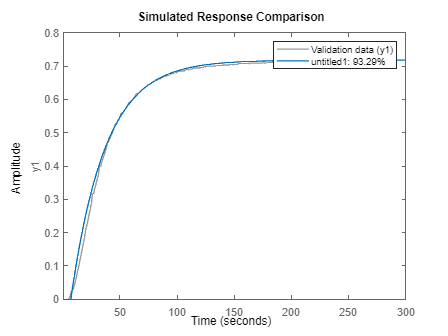

id1rz(k1, T1, theta1, y1, t)

#### Obiekt 2

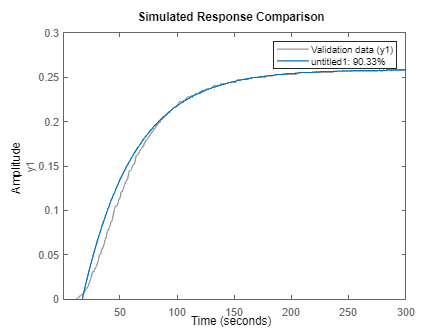

id1rz(k2, T2, theta2, y2, t)

#### Obiekt 3

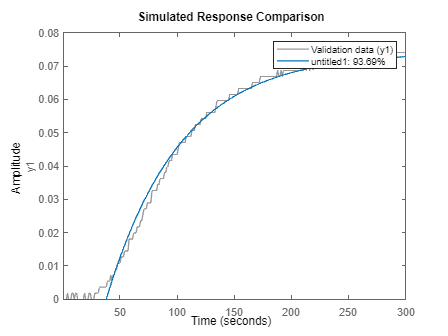

id1rz(k3, T3, theta3, y3, t)

### Aproksymacja Kupfmullera obiektem 2rz z opóźnieniem

Do kolejnych aproksymacji została zastosowana metoda fminsearch stosująca mfunkcje o następującej strukturze

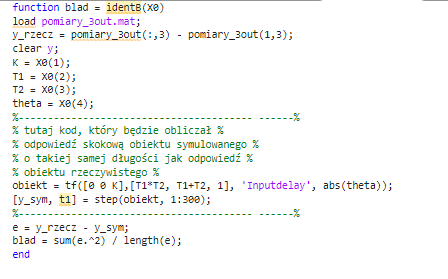

#### Obiekt1

K0 = 1; T1 = 5; T2 = 5; theta = 3;
[par, blad] = fminsearch('identB1',[K0,T1,T2,theta]);
par

par =     0.7132    4.7081   27.3659   -5.6119


obiektA24 = tf([0 0 par(1)], [par(3)*par(2) par(2)+par(3) 1], 'Inputdelay', abs(par(4)))

obiektA24 =
 
                         0.7132
  exp(-5.61*s) * -----------------------
                 128.8 s^2 + 32.07 s + 1
 
Continuous-time transfer function.



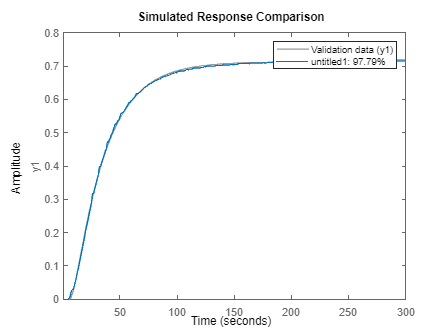

y = step(obiektA24, t);
figure
title("Obiekt C, metoda 2.4")
compare(iddata(y, ones(size(y)), 1), iddata(y1, ones(size(y)), 1))

#### Obiekt2

K0 = k2; T1 = 5; T2 = 5; theta = 10;
[par, blad] = fminsearch('identB2',[K0,T1,T2,theta]);
par

par =     0.2573   39.2450   10.4565   14.8580


obiektA24 = tf([0 0 par(1)], [par(3)*par(2) par(2)+par(3) 1], 'Inputdelay', abs(par(4)))

obiektA24 =
 
                         0.2573
  exp(-14.9*s) * ----------------------
                 410.4 s^2 + 49.7 s + 1
 
Continuous-time transfer function.



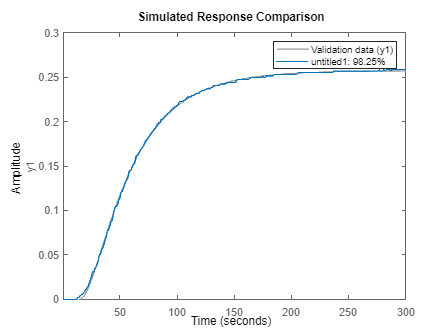

y = step(obiektA24, t);
figure
title("Obiekt C, metoda 2.4")
compare(iddata(y, ones(size(y)), 1), iddata(y2, ones(size(y)), 1))

#### Obiekt3

K0 = k2; T1 = 5; T2 = 5; theta = 10;
[par, blad] = fminsearch('identB3',[K0,T1,T2,theta]);
par

par =     0.0735   24.8261   51.0234  -24.8344


obiektA24 = tf([0 0 par(1)], [par(3)*par(2) par(2)+par(3) 1], 'Inputdelay', abs(par(4)))

obiektA24 =
 
                        0.07347
  exp(-24.8*s) * ----------------------
                 1267 s^2 + 75.85 s + 1
 
Continuous-time transfer function.



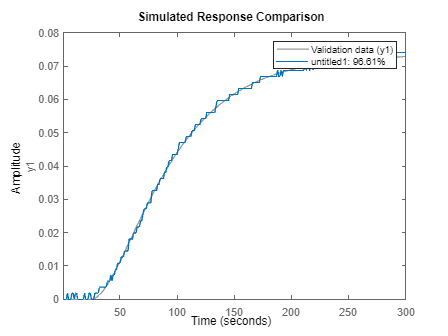

y = step(obiektA24, t);
figure
title("Obiekt C, metoda 2.4")
compare(iddata(y, ones(size(y)), 1), iddata(y3, ones(size(y)), 1))

### Aproksymacja Strejca obiektem N rzedu

#### Obiekt1

obiekt =
 
          0.7107
  -----------------------
  330.9 s^2 + 36.38 s + 1
 
Continuous-time transfer function.



par =     0.7107   18.1917


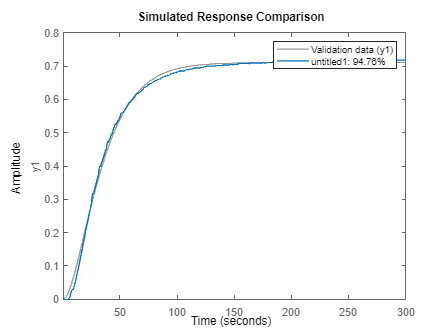

N = 2:6;
K0 = 2;
T0 = 10;
global n;
for i = N
    n=i;
    [par, blad] = fminsearch('identC1',[K0,T0]);
    s = tf('s');
    obiekt =  par(1) * (1/(par(2)*s + 1))^i;
    y_sym = step(obiekt, t);
    figure
    blod = num2str(blad);
    if i == 2
    obiekt
    par
    compare(iddata(y_sym, ones(size(y)), 1), iddata(y1, ones(size(y)), 1))
    end
end

#### Obiekt2

obiekt =
 
               0.2547
  ---------------------------------
  8634 s^3 + 1263 s^2 + 61.55 s + 1
 
Continuous-time transfer function.



par =     0.2547   20.5153


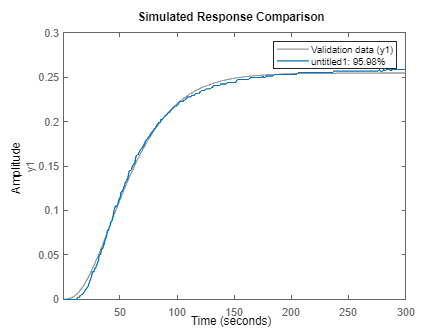

N = 2:6;
K0 = 2;
T0 = 10;
global n;
for i = N
    n=i;
    [par, blad] = fminsearch('identC2',[K0,T0]);
    s = tf('s');
    obiekt =  par(1) * (1/(par(2)*s + 1))^i;
    y_sym = step(obiekt, t);
    figure
    blod = num2str(blad);
    if i == 3
        obiekt
        par
        compare(iddata(y_sym, ones(size(y)), 1), iddata(y2, ones(size(y)), 1))
    end
end

#### Obiekt3

obiekt =
 
                        0.07172
  ----------------------------------------------------
  3.188e05 s^4 + 5.367e04 s^3 + 3388 s^2 + 95.05 s + 1
 
Continuous-time transfer function.



par =     0.0717   23.7627


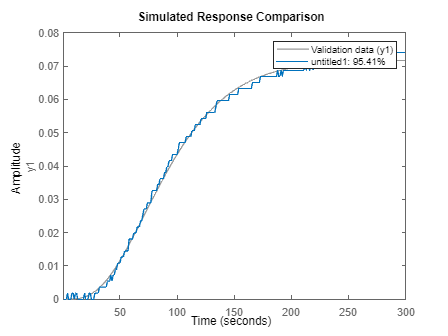

N = 2:6;
K0 = 2;
T0 = 10;
global n;
for i = N
    n=i;
    [par, blad] = fminsearch('identC3',[K0,T0]);
    s = tf('s');
    obiekt =  par(1) * (1/(par(2)*s + 1))^i;
    y_sym = step(obiekt, t);
    figure
    blod = num2str(blad);
    if i == 4
        obiekt
        par
        compare(iddata(y_sym, ones(size(y)), 1), iddata(y3, ones(size(y)), 1))
    end
end

Funkcja do zadania 1

function [] = id1rz(k, T, theta, y, t)
obiektA21 = tf([0 k], [T 1], 'Inputdelay', theta);
[yA1, tA1] = step(obiektA21, t);
figure
hold on; grid on;
plot(tA1, yA1, t, y)
hold off;
compare(iddata(y, ones(size(y)), 1), iddata(yA1, ones(size(y)), 1))
end

## Wnioski

Identyfikacja obiektów dynamicznych w matlabie jest dość łatwa. Najczęściej aby uzyskać zadowalający wynik wystarczy aproksymacja Kupfmullera 2rz. W tym ćwiczeniu dobrze było stosować fminsearch() gdyż automatyzacja znacząco ułatwia pracę.